pcdDir = "/Volumes/Expansion/Calibration/ecal_meas/2023-02-04_16-37-41.815_wildpose_v1.1/lidar/";
pcdFileNames = [
"livox_frame_1675521461_833648976.pcd"
"livox_frame_1675521461_933804176.pcd"
"livox_frame_1675521462_033678320.pcd"
"livox_frame_1675521462_132767536.pcd"
"livox_frame_1675521462_233678128.pcd"
"livox_frame_1675521462_333760688.pcd"
"livox_frame_1675521462_433836464.pcd"
"livox_frame_1675521462_533787344.pcd"
"livox_frame_1675521462_632725936.pcd"
"livox_frame_1675521462_733568624.pcd"
"livox_frame_1675521462_833829840.pcd"
"livox_frame_1675521462_933764432.pcd"
"livox_frame_1675521463_032756112.pcd"
"livox_frame_1675521463_132728688.pcd"
"livox_frame_1675521463_233619120.pcd"
"livox_frame_1675521463_333698992.pcd"
"livox_frame_1675521463_433718672.pcd"
"livox_frame_1675521463_532728368.pcd"
"livox_frame_1675521463_632792688.pcd"
"livox_frame_1675521463_733716880.pcd"
"livox_frame_1675521463_833808336.pcd"
"livox_frame_1675521463_933773584.pcd"
"livox_frame_1675521464_032716080.pcd"
"livox_frame_1675521464_132803088.pcd"
"livox_frame_1675521464_233665072.pcd"
"livox_frame_1675521464_333832272.pcd"
"livox_frame_1675521464_433704336.pcd"
"livox_frame_1675521464_532718416.pcd"
"livox_frame_1675521464_632795280.pcd"
"livox_frame_1675521464_733698448.pcd"
"livox_frame_1675521464_833789328.pcd"
"livox_frame_1675521464_933745552.pcd"
"livox_frame_1675521465_032759248.pcd"
"livox_frame_1675521465_132786256.pcd"
"livox_frame_1675521465_233698416.pcd"
"livox_frame_1675521465_333799024.pcd"
"livox_frame_1675521465_433780240.pcd"
"livox_frame_1675521465_532895792.pcd"
"livox_frame_1675521465_632829296.pcd"
"livox_frame_1675521465_733761904.pcd"
"livox_frame_1675521465_833823344.pcd"
"livox_frame_1675521465_933746416.pcd"
"livox_frame_1675521466_032751472.pcd"
"livox_frame_1675521466_132813648.pcd"
"livox_frame_1675521466_233681552.pcd"
"livox_frame_1675521466_333801456.pcd"
"livox_frame_1675521466_433739824.pcd"
"livox_frame_1675521466_532793904.pcd"
"livox_frame_1675521466_632810032.pcd"
"livox_frame_1675521466_733743440.pcd"
]

pcdFileNames = 50×1 string array
    "livox_frame_1675521461_833648976.pcd"
    "livox_frame_1675521461_933804176.pcd"
    "livox_frame_1675521462_033678320.pcd"
    "livox_frame_1675521462_132767536.pcd"
    "livox_frame_1675521462_233678128.pcd"
    "livox_frame_1675521462_333760688.pcd"
    "livox_frame_1675521462_433836464.pcd"
    "livox_frame_1675521462_533787344.pcd"
    "livox_frame_1675521462_632725936.pcd"
    "livox_frame_1675521462_733568624.pcd"
    "livox_frame_1675521462_833829840.pcd"
    "livox_frame_1675521462_933764432.pcd"
    "livox_frame_1675521463_032756112.pcd"
    "livox_frame_1675521463_132728688.pcd"
    "livox_frame_1675521463_233619120.pcd"
    "livox_frame_1675521463_333698992.pcd"
    "livox_frame_1675521463_433718672.pcd"
    "livox_frame_1675521463_532728368.pcd"
    "livox_frame_1675521463_632792688.pcd"
    "livox_frame_1675521463_733716880.pcd"
    "livox_frame_1675521463_833808336.pcd"
    "livox_frame_1675521463_933773584.pcd"
    "livox_frame_1675

## Merge

% Initialize ptCloud using the first file
filepath = fullfile(pcdDir, pcdFileNames(1));
ptCloud = pcread(filepath);

% Load and merge the next set of point clouds
for i = 2:length(pcdFileNames)
    filepath = fullfile(pcdDir, pcdFileNames(i));
    tmpPtCloud = pcread(filepath);
    ptCloud = pcmerge(ptCloud, tmpPtCloud, 0.001); % Using a merge tolerance of 0.001, adjust accordingly
end

pcwrite( ...
    ptCloud, ...
    fullfile( ...
        "/Users/ikuta/Documents/Projects/wildpose-applications/results/", ...
        "merge_00.pcd" ...
   ) ...
)

## Visualization

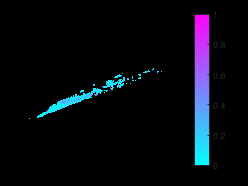

pcshow(ptCloud.Location, ptCloud.Intensity / max(ptCloud.Intensity))
title(filepath, 'Interpreter','none')
xlabel("X")
ylabel("Y")
zlabel("Z")
colorbar
colormap("cool")